
filename = 'fulldata.xlsx';
cdata = readmatrix(filename);
disp(size(cdata));

        2518          10




cdata1 = cdata(1:2517,:);

% Compute returns
returns = diff(cdata1) ./ cdata1(1:end-1, :);

% Split into in-sample and out-of-sample
inSampleSize = round(0.7 * size(returns, 1)); % 70% in-sample
in_sample_returns = returns(1:inSampleSize, :);
out_sample_returns = returns(inSampleSize+1:end, :);
% in_sample_returns = returns(1:15, :); % First 15 observations for in-sample
% out_sample_returns = returns(16:end, :); % Remaining for out-of-sample

% Estimate in-sample mean and covariance matrix
in_sample_mean = mean(in_sample_returns)';
in_sample_cov = cov(in_sample_returns);

% Perform PCA on the in-sample covariance matrix
[coeff, latent, explained] = pcacov(in_sample_cov);

% Determine the number of principal components to retain
explained_variance = cumsum(explained);
num_components = find(explained_variance >= evc, 1); %we can change this, varying this allows us to experiment and decide what we can change here, how it affects computation time
disp(num_components);

    10




% Reduce the dimensionality
coeff_reduced = coeff(:, 1:num_components);
latent_reduced = latent(1:num_components);

% Reconstruct the mean and covariance matrix in the reduced subspace
mean_reduced = coeff_reduced' * in_sample_mean;
cov_reduced = diag(latent_reduced);

% Transform the mean and covariance matrix back to the original space
in_sample_mean_reconstructed = coeff_reduced * mean_reduced;
in_sample_cov_reconstructed = coeff_reduced * cov_reduced * coeff_reduced';

% % Create a portfolio object
p = Portfolio;


% Set asset mean returns and covariance matrix
p = p.setAssetMoments(in_sample_mean_reconstructed, in_sample_cov_reconstructed);

% Set portfolio constraints
p = p.setDefaultConstraints;

% Perform mean-variance portfolio optimization
pwgt = estimateFrontier(p);
a = pwgt(:,1);

% Display optimal portfolio weights
disp(pwgt);

    0.0762    0.0916    0.1006    0.1084    0.0952    0.0816         0         0         0         0
    0.0832    0.1045    0.1130    0.1194    0.0894    0.0579         0         0         0         0
    0.0109    0.0673    0.1301    0.1928    0.2533    0.3135    0.2743    0.1065         0         0
         0    0.0375    0.0879    0.1395    0.2101    0.2811    0.4121    0.5878    0.7776    1.0000
    0.0078    0.0366    0.0663    0.0964    0.1336    0.1709    0.2060    0.2203    0.2108         0
    0.2540    0.1973    0.0949         0         0         0         0         0         0         0
    0.3953    0.3787    0.3417    0.2988    0.1486         0         0         0         0         0
    0.0750         0         0         0         0         0         0         0         0         0
    0.0976    0.0794    0.0398         0         0         0         0         0         0         0
         0    0.0070    0.0256    0.0446    0.0698    0.0950    0.1077    0.0855    0.0116 

portfolio_stdev = zeros(length(pwgt),1);
for i = 1:length(pwgt)
    portfolio_stdev(i) = sqrt(pwgt(:,i)' * in_sample_cov_reconstructed * pwgt(:,i));
end
portfolio_returns1 = pwgt' * in_sample_mean_reconstructed;
maxmin = 0;
maxminpf = 0;
temp = 0;
for j = 1:length(pwgt)
    temp = portfolio_returns1(j) / portfolio_stdev(j);
    disp('current sharpe ratio')
    disp(j);
    disp(temp);
    if (maxmin<temp)
        maxmin = temp;
        maxminpf = j;
    end
end

current sharpe ratio


     1



    0.0571



current sharpe ratio


     2



    0.0796



current sharpe ratio


     3



    0.0941



current sharpe ratio


     4



    0.1007



current sharpe ratio


     5



    0.1017



current sharpe ratio


     6



    0.0997



current sharpe ratio


     7



    0.0957



current sharpe ratio


     8



    0.0896



current sharpe ratio


     9



    0.0833



current sharpe ratio


    10



    0.0769



printout = sprintf('Portfolio %d is the portfolio offering the most return considering risk', maxminpf);
disp(printout);

Portfolio 5 is the portfolio offering the most return considering risk


EFpoints = [portfolio_stdev, portfolio_returns1];
disp(EFpoints);

    0.0078    0.0004
    0.0081    0.0006
    0.0089    0.0008
    0.0103    0.0010
    0.0122    0.0012
    0.0144    0.0014
    0.0170    0.0016
    0.0204    0.0018
    0.0243    0.0020
    0.0289    0.0022



%coordinates_array = table2array(EFpoints);

% Plot efficient frontier

figure;
hold;

Current plot held


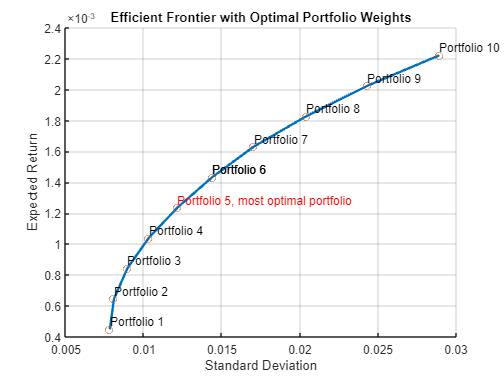

plotFrontier(p);

% Calculate standard deviation for each portfolio

%add risk bias



% Plot optimal portfolio weights on the efficient frontier
plot(portfolio_stdev, portfolio_returns1 , 'o' );

% Label the points
for i = 1:length(pwgt)
    if (i == maxminpf)
        
        text(portfolio_stdev(maxminpf), portfolio_returns1(maxminpf), sprintf('Portfolio %d, most optimal portfolio', i),'Color','r','HorizontalAlignment','left','VerticalAlignment','bottom');
        i = i+1;
    end
    text(portfolio_stdev(i), portfolio_returns1(i), sprintf('Portfolio %d', i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
end

%text(portfolio_stdev(maxminpf), portfolio_returns1(maxminpf), 'Best Portfolio', 'FontSize',12,'Color','r','HorizontalAlignment','right','VerticalAlignment','bottom');

xlabel('Standard Deviation');
ylabel('Expected Return');
title('Efficient Frontier with Optimal Portfolio Weights');
hold off;


optimalweight = pwgt(:,maxminpf);
disp('the optimal weightage for the 10 assets is');

the optimal weightage for the 10 assets is


disp(optimalweight);

    0.0952
    0.0894
    0.2533
    0.2101
    0.1336
         0
    0.1486
         0
         0
    0.0698

